% Initialization
close all
clear
clc

% Symbolic variables
syms x y t n_x n_y real
X=[x,y];
n=[n_x;n_y];

% Parameters
syms epsilon_p rho_1 rho_2 g_x g_y a real
g=[g_x;g_y];

% Analytical solution
P=1-x;
S=1/(exp(a*(x-t))+1);

% Saturation-dependent parameters
K11=[  1-S      0
        0      1-S  ];
K12=[S*(1-S)    0
        0    S*(1-S)];
K21=[S*(1-S)    0
        0    S*(1-S)];
K22=[   S       0
        0       S   ];
G=1-2*S;

% Sources
q1=+(a*rho_1*(2*exp(a*(2*t+3*x))+4*exp(a*(3*t+2*x))+2*exp(a*(4*t+x))-2*a*exp(a*(t+4*x))-epsilon_p*exp(a*(t+4*x))-epsilon_p*exp(a*(4*t+x))+6*a*exp(a*(2*t+3*x))-3*epsilon_p*exp(a*(2*t+3*x))-3*epsilon_p*exp(a*(3*t+2*x))+g_x*rho_1*exp(a*(t+4*x))+g_x*rho_1*exp(a*(4*t+x))-g_x*rho_2*exp(a*(t+4*x))+g_x*rho_2*exp(a*(4*t+x))+3*g_x*rho_1*exp(a*(2*t+3*x))+3*g_x*rho_1*exp(a*(3*t+2*x))-g_x*rho_2*exp(a*(2*t+3*x))+g_x*rho_2*exp(a*(3*t+2*x))))/(10*exp(a*(2*t+3*x))+10*exp(a*(3*t+2*x))+exp(5*a*t)+exp(5*a*x)+5*exp(a*(t+4*x))+5*exp(a*(4*t+x)));
q2=-(a*rho_2*(4*exp(a*(2*t+3*x))+2*exp(a*(3*t+2*x))+2*exp(a*(t+4*x))+2*a*exp(a*(4*t+x))-epsilon_p*exp(a*(t+4*x))-epsilon_p*exp(a*(4*t+x))-6*a*exp(a*(3*t+2*x))-3*epsilon_p*exp(a*(2*t+3*x))-3*epsilon_p*exp(a*(3*t+2*x))+g_x*rho_1*exp(a*(t+4*x))-g_x*rho_1*exp(a*(4*t+x))+g_x*rho_2*exp(a*(t+4*x))+g_x*rho_2*exp(a*(4*t+x))+g_x*rho_1*exp(a*(2*t+3*x))-g_x*rho_1*exp(a*(3*t+2*x))+3*g_x*rho_2*exp(a*(2*t+3*x))+3*g_x*rho_2*exp(a*(3*t+2*x))))/(10*exp(a*(2*t+3*x))+10*exp(a*(3*t+2*x))+exp(5*a*t)+exp(5*a*x)+5*exp(a*(t+4*x))+5*exp(a*(4*t+x)));

% Normal momentum
f1=-rho_1*dot((K11*(-mygradient(P,X)'+mygradient(G,X)'+rho_1*g)+...
               K12*(-mygradient(P,X)'-mygradient(G,X)'+rho_2*g)),n);
f2=-rho_2*dot((K21*(-mygradient(P,X)'+mygradient(G,X)'+rho_1*g)+...
               K22*(-mygradient(P,X)'-mygradient(G,X)'+rho_2*g)),n);

% Check residual 1
R1=simplify(...
   -epsilon_p*diff(rho_1*S,t)...
   +mydivergence(rho_1*(K11*(-mygradient(P,X)'+mygradient(G,X)'+rho_1*g)+...
                        K12*(-mygradient(P,X)'-mygradient(G,X)'+rho_2*g)),X)...
   -q1)

$$R1 = 0$$


% Check residual 2
R2=simplify(...
   +epsilon_p*diff(rho_2*S,t)...
   +mydivergence(rho_2*(K21*(-mygradient(P,X)'+mygradient(G,X)'+rho_1*g)+...
                        K22*(-mygradient(P,X)'-mygradient(G,X)'+rho_2*g)),X)...
   -q2)

$$R2 = 0$$

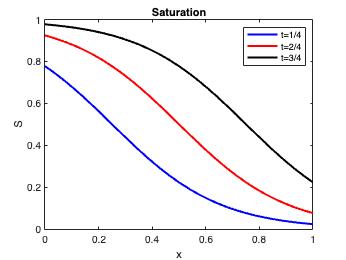


% Numerical values
epsilon_p=1/2; rho_1=1; rho_2=1; g=[0;0]; a=5;

% Plot saturation
figure
fplot(x,subs(eval(S),t,1/4),[0,1],'b','LineWidth',2)
hold on
fplot(x,subs(eval(S),t,2/4),[0,1],'r','LineWidth',2)
fplot(x,subs(eval(S),t,3/4),[0,1],'k','LineWidth',2)
hold off
xlim([0,1])
ylim([0,1])
title('Saturation')
xlabel('x')
ylabel('S')
legend({'t=1/4','t=2/4','t=3/4'})